# Practice NODC Cast work

% Load Data
cd('C:\Users\ajs82292\Desktop\Research\Matlab\Source')
load("02cleanNODC.mat")

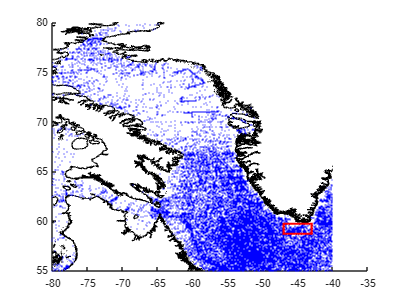

% Map
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Limit NODC Data to Square only to make interpolation easier
Squarelonindicies = (lon >= -47) & (lon <=-43) ;
lon = lon(Squarelonindicies) ;
lat = lat(Squarelonindicies) ;
sal = sal(Squarelonindicies) ;
temp = temp(Squarelonindicies) ;
mon = mon(Squarelonindicies);
day = day(Squarelonindicies);
yea = yea(Squarelonindicies);
watdep = watdep(Squarelonindicies);
dep = dep(Squarelonindicies) ;
% Lat
Squarelatindicies = (lat >= 58.7) & (lat <=59.7) ;
lon = lon(Squarelatindicies) ;
lat = lat(Squarelatindicies) ;
sal = sal(Squarelatindicies) ;
temp = temp(Squarelatindicies) ;
mon = mon(Squarelatindicies) ;
day = day(Squarelatindicies);
yea = yea(Squarelatindicies);
watdep = watdep(Squarelatindicies) ;
dep = dep(Squarelatindicies) ;

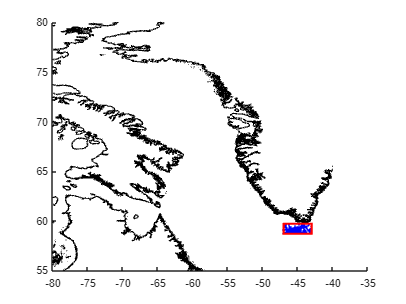

%Map New Restricted Data
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(lon,lat,2,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
rectangle('Position',[-47,58.7,4,1],'EdgeColor','red','LineWidth',2)
hold off

%Interpolate every 1 m 
max_length = max(cellfun(@numel,dep)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
for i = 1:1:length(dep)
    int_temp{1,i} = interp1(dep{1,i},temp{1,i}, DepInterval, 'linear') ;
end
%Salinity 
int_sal = {} ;
for i = 1:1:length(dep)
    int_sal{1,i} = interp1(dep{1,i},sal{1,i}, DepInterval, 'linear') ;
end

% Set Up Month Matrices
Julyindex = (mon == 7);
Augindex = (mon == 8);
Septindex = (mon == 9);
Octindex = (mon == 10);
JulyT = int_temp(Julyindex) ;
AugT = int_temp(Augindex) ;
SeptT = int_temp(Septindex) ;
OctT = int_temp(Octindex) ;
JulyS = int_sal(Julyindex) ;
AugS = int_sal(Augindex) ;
SeptS = int_sal(Septindex) ;
OctS = int_sal(Octindex) ;
% Matrices for Calculations
JulyT = cell2mat(JulyT);
AugT = cell2mat(AugT);
SeptT = cell2mat(SeptT);
OctT = cell2mat(OctT);
JulyS = cell2mat(JulyS);
AugS = cell2mat(AugS);
SeptS = cell2mat(SeptS);
OctS = cell2mat(OctS);

% Computations
%Averages
JulyTM = mean(JulyT, 2, 'omitnan') ;
AugTM = mean(AugT, 2, 'omitnan') ;
SeptTM = mean(SeptT, 2, 'omitnan') ;
OctTM = mean(OctT, 2, 'omitnan') ;
JulySM = mean(JulyS, 2, 'omitnan') ;
AugSM = mean(AugS, 2, 'omitnan') ;
SeptSM = mean(SeptS, 2, 'omitnan') ;
OctSM = mean(OctS, 2, 'omitnan') ;
% Standard Deviations
JulyTStd = std(JulyT, 0, 2, 'omitnan') ;
AugTStd = std(AugT, 0, 2, 'omitnan') ;
SeptTStd = std(SeptT, 0, 2, 'omitnan') ;
OctTStd = std(OctT, 0, 2, 'omitnan') ;
JulySStd = std(JulyS, 0, 2, 'omitnan');
AugSStd = std(AugS, 0, 2, 'omitnan');
SeptSStd = std(SeptS, 0, 2, 'omitnan');
OctSStd = std(OctS, 0, 2, 'omitnan');

% Subtract Each Cast by monthly Average for Anomaly
JulyTA = JulyT - JulyTM ;
JulySA = JulyS - JulySM ;
AugTA = AugT - AugTM ;
AugSA = AugS - AugSM ;
SeptTA = SeptT - SeptTM ;
SeptSA = SeptS - SeptSM ;
OctTA = OctT - OctTM ;
OctSA = OctS - OctSM ;

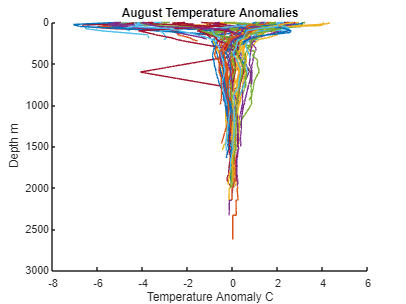

%August TA
clf
hold on
plot(AugTA,DepInterval)
title('August Temperature Anomalies')
xlabel('Temperature Anomaly C')
ylabel('Depth m')
axis ij
hold off

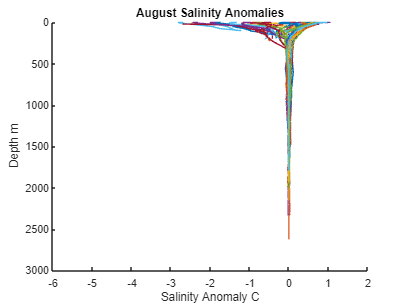

%August Salinity Anmoaly
clf
hold on
plot(AugSA,DepInterval)
title('August Salinity Anomalies')
xlabel('Salinity Anomaly C')
ylabel('Depth m')
axis ij
hold off

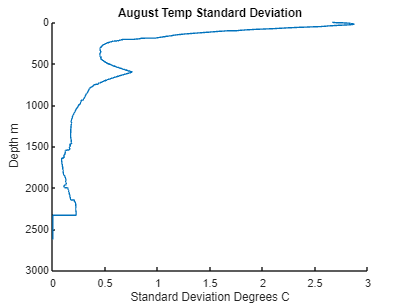

% August Temperature Std
clf
hold on
plot(AugTStd,DepInterval)
title('August Temp Standard Deviation')
xlabel('Standard Deviation Degrees C')
ylabel('Depth m')
axis ij
hold off

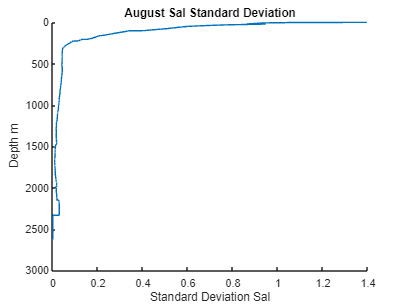

% August Salinity Std
clf
hold on
plot(AugSStd,DepInterval)
title('August Sal Standard Deviation')
xlabel('Standard Deviation Sal')
ylabel('Depth m')
axis ij
hold off

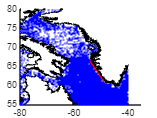

% Work on simplified coastline (ginput) (Needs to have better coast
% selection)
clf
hold on
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
% Already selected coastline points
run = 2 ;
for i = 1:1:1
    if run == i 
        SWgcoast = ginput(2);
        save ("SWgcoast.mat", "SWgcoast");
    end
end
load('SWgcoast.mat')
scatter(lon,lat,1,'MarkerFaceColor','b','MarkerEdgeAlpha','0') ;
plot (SWgcoast(:,1),SWgcoast(:,2) ,'r')
hold off

% Creation of Parallelograms on SW Coast
m = ((SWgcoast(2,2)-SWgcoast(1,2))/(SWgcoast(2,1)-SWgcoast(1,1))) ; %slope of simplified coastline
recwidth = 20*2 ; % km doubled as it is 10 "radius"
reclength = 60*2 ; % km doubled as it is 20 "radius"
y_SWcoast = [SWgcoast(2,2),SWgcoast(1,2)] ; 
x_SWcoast = [SWgcoast(2,1), SWgcoast(1,1)] ; 
dx = SWgcoast(2,2) - SWgcoast(1,2) ;
dy = SWgcoast(2,1) - SWgcoast(1,1) ;
lengthdeg = km2deg(reclength) ;
widthdeg = 111.320 .*cosd(lat) ;
widthdeg = recwidth./widthdeg ;
SWwidthdeg = 111.320* cosd(y_SWcoast) ;
SWwidthdeg = recwidth./SWwidthdeg ;

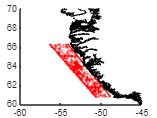

% Find Casts within defined area (NEEDS TO BE RUN AT 10x20 AND THEN
% ALTERED!)
x5_SWcoast = x_SWcoast - 5*SWwidthdeg ;
SW_xcombined = [x5_SWcoast,flip(x_SWcoast)] ; % counterclockwise verticies order
SW_ycombined = [y_SWcoast,flip(y_SWcoast)] ; % counterclockwise verticies order
SWidx = inpolygon(lon,lat, SW_xcombined,SW_ycombined) ;
% Isolate SW variables
SW_lon = lon(SWidx) ;
SW_lat = lat(SWidx) ;
SW_watdep = watdep(SWidx);
SW_sal = sal(SWidx);
SW_temp = temp(SWidx);
SW_dep = dep(SWidx) ;
SW_yea = yea(SWidx);
SW_day = day(SWidx);
SW_mon = mon(SWidx);
SW_widthdeg = widthdeg(SWidx) ;
%Plot
clf
hold on 
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
plot(cx,cy, 'k')
xlim([-60,-45])
ylim([60,70])
scatter(SW_lon,SW_lat,1,'MarkerFaceColor','r','MarkerEdgeAlpha','0') ;
hold off

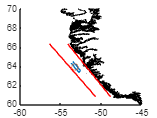

% Defining parallelogram verticies for casts (length and width not correct)
lengthrad = deg2rad(lengthdeg) ;
lengthdeg = ones(1,length(SW_widthdeg)).*lengthdeg ;
widthrad = deg2rad(SW_widthdeg) ;
half_length = lengthdeg./1.6 ; % mess with the divisibles to get the km right (this is within 1 km after limited testing)
half_width = SW_widthdeg./3; %  mess with the divisibles to get the km right (this is within 1 km after limited testing)
for i = 1:numel(SW_lon)
    % Calculate the coordinates of the vertices
    vertex1 = [SW_lon(i) - half_width; SW_lat(i) + half_length]; %careful, longitude is negative so watch signs
    vertex2 = [SW_lon(i) - half_width; SW_lat(i) - half_length];
    vertex3 = [SW_lon(i) + half_width; SW_lat(i) - half_length];
    vertex4 = [SW_lon(i) + half_width; SW_lat(i) + half_length];
    % Arrange vertices in counterclockwise order
    vertices = [vertex1(:,i), vertex2(:,i), vertex3(:,i), vertex4(:,i)];
    % Store in cell array
    vertices_cell{i} = vertices;
end
% Rotate Verticies to allign with angle to coast
SW_angle = atan2d(dx,dy) ; % degrees
bearing = SW_angle - 90 ; % find angle in relation to y-axis
R = [cosd(bearing), -sind(bearing); sind(bearing), cosd(bearing)];
for i = 1:length(vertices_cell)
center_x = vertices_cell{i}(1,:) - SW_lon(i);
center_y = vertices_cell{i}(2,:) - SW_lat(i);
SW_rotated = R * [center_x;center_y] ;
SW_rotated_cell{i} = SW_rotated ;
SW_xrotated = SW_rotated_cell{i}(1,:) + SW_lon(i) ;
SW_yrotated = SW_rotated_cell{i}(2,:) + SW_lat(i) ;
SW_xrotatedcell{i} = SW_xrotated ;
SW_yrotatedcell{i} = SW_yrotated ;
SW_rotated_verticies = [SW_xrotatedcell{i};SW_yrotatedcell{i}] ;
SW_rotvertcell{i} = SW_rotated_verticies ;
end
clear('SW_rotated_verticies')
clear('SW_yrotated')
clear('SW_xrotated')
clear('SW_rotated_cell')
clear('SW_yrotated')
clear('SW_xrotated')
clear('SW_yrotatedcell')
clear('SW_xrotatedcell')
clear('SW_rotated_cell')
clear('SW_rotated')
%Plot Angled Rectangles
clf
hold on
plot(SW_rotvertcell{1}(1,:),SW_rotvertcell{1}(2,:) )
scatter(SW_lon(1,1),SW_lat(1,1))
plot(cx,cy,' k')
xlim([-60,-45])
ylim([60,70])
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
hold off

% Clear Unneeded variables
clear('verex1')
clear('verex2')
clear('verex3')
clear('verex4')
clear('R')
% Rectangle Calculations
% Interpolate every 1 m for the SW coastal region
max_length = max(cellfun(@numel,SW_dep)) ;
DepInterval = (0:1:max_length)';
int_temp = {} ;
run = 2 ;
for i = 1:1:length(SW_dep)
    if run == 1 
        SW_int_temp{1,i} = interp1(SW_dep{1,i},SW_temp{1,i}, DepInterval, 'linear') ;
        save ("SW_int_temp.mat", "SW_int_temp");
    end
end
    load('SW_int_temp.mat')
%Salinity 
int_sal = {} ;
for i = 1:1:length(SW_dep)
   if run == 1
    SW_int_sal{1,i} = interp1(SW_dep{1,i},SW_sal{1,i}, DepInterval, 'linear') ;
     save ("SW_int_sal.mat", "SW_int_sal");
   end
end
load('SW_int_sal.mat')
% Create 15 day indicies regardless of year 
SW_date = ([SW_yea; SW_mon; SW_day]) ;
SW_date(4,:) = datenum(0,SW_date(2,:),SW_date(3,:));% everything set in the year 0 to make for easy sorting by day and month
SW_datenum = datenum(0,SW_date(2,:),SW_date(3,:)) ;% everything set in the year 0 to make for easy sorting by day and month
day_range = 15 ; % adjust this as needed
middle_idx = SW_date(4,:) >= day_range & SW_date(4,:) <= 365-day_range;
earlyjan_idx = (SW_date(4,:) < day_range) ; % only includes earliest part of Jan that overlaps with interval 
latedec_idx = (SW_date(4,:) > 365-day_range); % only includes latest part of Dec that overlaps with interval 
Jan_range = 365-day_range + (SW_datenum(earlyjan_idx) ); % Earliest Day to include
Jan_range(2,:) = SW_datenum(earlyjan_idx)+day_range ; % Latest Day to include
Middle_range = SW_datenum(middle_idx)- day_range ;
Middle_range(2,:) = SW_datenum(middle_idx)+ day_range ;
Dec_range = SW_datenum(latedec_idx)- day_range ;
Dec_range(2,:) = SW_datenum(latedec_idx)-365+day_range;
SW_ranges = [Jan_range,Middle_range,Dec_range] ;
clear('middle_idx')
clear('earlyjan_idx')
clear('latedec_idx')

% Create indicies for individual rectangles 
for i = 1:length(SW_rotvertcell)
   SW_poly_idx = inpolygon(SW_lon,SW_lat,SW_rotvertcell{i}(1,:),SW_rotvertcell{i}(2,:)) ;
   SW_poly_idxcell{i} = SW_poly_idx ;
end
clear('SW_poly_idx')
% Create indicies for dates
jan_idx = false(1,length(SW_ranges)) ;
Middle_idx = false(1,length(SW_ranges)) ;
dec_idx = false(1,length(SW_ranges)) ;
% Overlapping January Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Jan_range)
    if SW_datenum(i) >= Jan_range(1,j) | SW_datenum(i) <= Jan_range(2,j)
        jan_idx(i) = 1 ;
        Jan_cell{j} = jan_idx ;
    end
    end
end
% Middle Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Middle_range)
    if SW_datenum(i) >= Middle_range(1,j) & SW_datenum(i) <= Middle_range(2,j)
Middle_idx(i) = 1;
Middle{j} = Middle_idx ;
    end
    end
end
% Overlapping Dec Dates
for i = 1:length(SW_ranges)
    for j = 1:length(Dec_range)
         if SW_datenum(i) >= Dec_range(1,j) | SW_datenum(i) <= Dec_range(2,j)
        dec_idx(i) = 1 ;
       Dec_cell{j} = dec_idx ;
    end
    end
end
% Concatenate Overlapping [Jan,Middle,Dec] cell arrays (Looks Correct but need to test
SW_date_idx_cell =  ([Jan_cell,Middle,Dec_cell]) ;
% Combine Date and Polygon indicies for temp and sal
for i = 1:length(SW_poly_idxcell)
    SW_poly_temp = SW_int_temp(SW_poly_idxcell{i} & SW_date_idx_cell{i}) ;
    SW_poly_temp_cell{i} = SW_poly_temp ;
end
for i = 1:length(SW_poly_idxcell)
    SW_poly_sal = SW_int_sal(SW_poly_idxcell{i} & SW_date_idx_cell{i}) ;
    SW_poly_sal_cell{i} = SW_poly_sal ;
end
% Calculate Means
counts = zeros(1,numel(SW_poly_temp_cell) );
max_length = max(counts) ;
for i = 1:length(SW_poly_sal_cell)
    insidearray = cell2mat(SW_poly_sal_cell{i}) ;
    SW_sal_expanded{1,i} = insidearray ;
end
for i = 1:length(SW_poly_temp_cell)
    insidearray = cell2mat(SW_poly_temp_cell{i}) ;
    SW_temp_expanded{1,i} = insidearray ;
end
% Means 
for i = 1:length(SW_sal_expanded)
    SW_means = mean(SW_sal_expanded{i},2,'omitnan') ;
    SW_sal_means_cell{i} = SW_means ;
end
for i = 1:length(SW_temp_expanded)
    SW_means = mean(SW_temp_expanded{i},2,'omitnan') ;
    SW_temp_means_cell{i} = SW_means ;
end
% Calculate Anomalies
for i = 1:length(SW_int_sal)
SW_Anmly = SW_sal_means_cell{i} - SW_int_sal{i} ;
SW_sal_Anmly_cell{i} = SW_Anmly ;
end
for i = 1:length(SW_int_temp)
SW_Anmly = SW_temp_means_cell{i} - SW_int_temp{i} ;
SW_temp_Anmly_cell{i} = SW_Anmly ;
end
clear('Jan_cell')
clear('Jan_idx')
clear('Jan_range')
clear('Dec_cell')
clear('Dec_idx')
clear('Dec_range')
clear('Middle')
clear('Middle_idx')
clear('Middle_range')
clear('SW_poly_temp')
clear('SW_poly_sal')

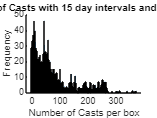

% Statistics
% Frequency of Counts
for i = 1:numel(SW_poly_temp_cell)
    % Get the current cell array
    subCellArray = SW_poly_temp_cell{i};
    % Count the number of elements in the current cell array
    counts(i) = numel(subCellArray);
end
%PlotHistogram (20x10 15 days)
clf
hold on
histogram(counts, 'BinMethod', 'integers');
xlabel('Number of Casts per box');
ylabel('Frequency');
title('Frequency of Casts with 15 day intervals and 60x15 km box');
hold off

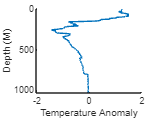

% Plot Example Salintiy Anomaly
clf
hold on
plot(SW_temp_Anmly_cell{1,113},DepInterval)
axis ij
xlabel('Temperature Anomaly')
ylabel('Depth (M)')
hold off

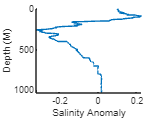

% Plot Example Temp Anomaly
clf
hold on
plot(SW_sal_Anmly_cell{1,113},DepInterval)
axis ij
xlabel('Salinity Anomaly')
ylabel('Depth (M)')
hold off

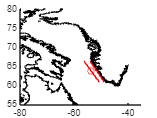

%Plot Example Station
clf
hold on
scatter(SW_lon(113),SW_lat(113), 'r')
xlim([-80,-35])
ylim([55,80])
plot(cx,cy, 'k')
plot(x_SWcoast,y_SWcoast, 'r')
plot(x5_SWcoast,y_SWcoast,'r')
hold off

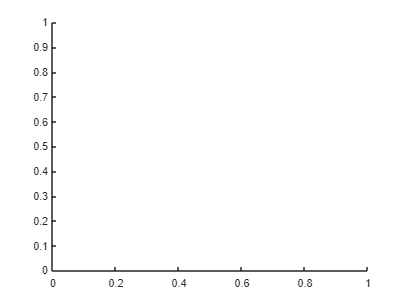

% Plot 
clf
hold on

for i = 1:numel(zeroten_cell)
plot(zeroten_cell{i}(:,1),zeroten_cell{i}(:,2), 'k')
plot(tentwenty_cell{i}(:,1),tentwenty_cell{i}(:,2),'k')
plot(twentythirty_cell{i}(:,1),twentythirty_cell{i}(:,2),'k')
plot(thirtyfourty_cell{i}(:,1),thirtyfourty_cell{i}(:,2),'k')
plot(fourtyfifty_cell{i}(:,1),fourtyfifty_cell{i}(:,2),'k')
plot(cx,cy, 'k')
xlim([-60,-45])
ylim([60,70])
end

Unrecognized function or variable 'zeroten_cell'.

hold off


% Sorting for Casts inside polygons 
for i = 1:1:numel(zeroten_cell)
zerotenidx = inpolygon(lon,lat, zeroten_cell{i}(:,1), zeroten_cell{i}(:,2)) ;
zeroten_idx_cell{i} = zerotenidx ;
end
for i = 1:1:numel(zeroten_cell)
tentwentyidx = inpolygon(lon,lat, tentwenty_cell{i}(:,1), tentwenty_cell{i}(:,2)) ;
tentwenty_idx_cell{i} = tentwentyidx ;
end
for i = 1:1:numel(zeroten_cell)
twentythirtyidx = inpolygon(lon,lat, twentythirty_cell{i}(:,1), twentythirty_cell{i}(:,2)) ;
twentythirty_idx_cell{i} = twentythirtyidx ;
end
for i = 1:1:numel(zeroten_cell)
thirtyfourtyidx = inpolygon(lon,lat, thirtyfourty_cell{i}(:,1), thirtyfourty_cell{i}(:,2)) ;
thirtyfourty_idx_cell{i} = thirtyfourtyidx ;
end
for i = 1:1:numel(zeroten_cell)
fourtyfiftyidx = inpolygon(lon,lat, fourtyfifty_cell{i}(:,1), fourtyfifty_cell{i}(:,2)) ;
fourtyfifty_idx_cell{i} = fourtyfiftyidx ;
end
%Plot
clf
hold on
for i = 1:numel(zeroten_cell)
plot(zeroten_cell{i}(:,1),zeroten_cell{i}(:,2), 'k')
end
for i = 1:1:numel(zeroten_idx_cell)
 scatter(lon(zeroten_idx_cell{i}(1,:)),lat(zeroten_idx_cell{i}(1,:)))
end
for i = 1:numel(zeroten_cell)
plot(tentwenty_cell{i}(:,1),tentwenty_cell{i}(:,2), 'k')
end
for i = 1:1:numel(zeroten_idx_cell)
 scatter(lon(tentwenty_idx_cell{i}(1,:)),lat(tentwenty_idx_cell{i}(1,:)))
end
for i = 1:numel(zeroten_cell)
plot(twentythirty_cell{i}(:,1),twentythirty_cell{i}(:,2), 'k')
end
for i = 1:1:numel(zeroten_idx_cell)
 scatter(lon(twentythirty_idx_cell{i}(1,:)),lat(twentythirty_idx_cell{i}(1,:)))
end
for i = 1:numel(zeroten_cell)
plot(thirtyfourty_cell{i}(:,1),thirtyfourty_cell{i}(:,2), 'k')
end
for i = 1:1:numel(zeroten_idx_cell)
 scatter(lon(thirtyfourty_idx_cell{i}(1,:)),lat(thirtyfourty_idx_cell{i}(1,:)))
end

for i = 1:numel(zeroten_cell)
plot(fourtyfifty_cell{i}(:,1),fourtyfifty_cell{i}(:,2), 'k')
end
for i = 1:1:numel(zeroten_idx_cell)
 scatter(lon(fourtyfifty_idx_cell{i}(1,:)),lat(fourtyfifty_idx_cell{i}(1,:)))
end
hold off

% Perform Anamoly Calculations


% Find nearest cx,cy and distance (need to fix shouldn't be linear)
coastlinepoints = [cx,cy] ;
lonlat = [lon',lat'] ;
idx_nearest = knnsearch(coastlinepoints, lonlat);
closest_cx = cx(idx_nearest);
closest_cy = cy(idx_nearest);
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ; % ' to translate lat lon
d_lat = lat' - closest_cy ; 
d_lon = lon' - closest_cx ;
angles = atan2d(d_lat,d_lon) ;
angles = mod(angles, 360);
rads = deg2rad(angles) ;

% Creation of angled ovals
clf
hold on
testx = [closest_cx(1,1),lon(1,1)] ;
testy = [closest_cy(1,1),lat(1,1)] ;
testx2 = [-53.5712,lon(1,1)] ;
testy2 = [58.2901,lat(1,1)] ;
tilt_angle = pi/2 ;
a = 3 ;
b = 1 ;
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,1), lat(1,1)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,1) ;
y = y - lat(1,1) ;
R = [cos(rads(1,1)+tilt_angle), -sin(rads(1,1)+tilt_angle); sin(rads(1,1)+tilt_angle), cos(rads(1,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,1) ;
y = y + lat(1,1) ;
plot(x,y)
scatter(closest_cx(1,1),closest_cy(1,1))
scatter(lon(1,1),lat(1,1))
plot(cx,cy, 'k')
xlim([-80,-35])
ylim([55,80])
plot(testx,testy)
plot(testx2,testy2)
hold off

% Major axis of ellipse
a_km = 7.5 ; % distance of major axis (this will change with distance from coastline)
lat1 = deg2rad(lat) ;
lon1 = deg2rad(lon) ;
bearing = rads ; % in radians
bearing = bearing' ;
R = 6371 ; % r of earth
d = a_km/R ; % Distance to Radians
lat2 = asin(sin(lat1) .* cos(d) + cos(lat1) .* sin(d) .* cos(bearing)) ;
lon2 = lon1 + atan2(real(sin(bearing) .* sin(d) .* cos(lat1)), real(cos(d) - sin(lat1) .* sin(lat2)));
lat2 = rad2deg(lat2) ;
lon2 = rad2deg(lon2) ;
latdiff = abs(lat2-lat) ; % degrees - degrees
londiff = abs(lon2-lon) ;
Amagnitudedistance = sqrt(latdiff.^2+londiff.^2) ;
%Minor Axis of Elipse (scaled to a)
asource = Amagnitudedistance ;
distances = sqrt((lon'-closest_cx).^2 +(lat'-closest_cy).^2) ;
equalization = 2.5 ; % distance at which a = b and becomes a circle
scaleb = min(1,distances/equalization) ;
scaleb = scaleb' ;
bsource =  min(asource,asource.*scaleb) ;

% Test, ensure B is never larger than a or the angle won't match
clf
hold on
indiv = 44 ;
tilt_angle = pi/2 ;
a = asource(1,indiv) ; % (Constant)
b = bsource(1,indiv) ; % b defined above
theta = linspace(0, 2*pi, 100) ; % Angles from 0-2pi
center = [lon(1,indiv), lat(1,indiv)] ;
x = center(1) + a * cos(theta) ;
y = center(2) + b * sin(theta) ;
x = x - lon(1,indiv) ;
y = y - lat(1,indiv) ;
R = [cos(rads(indiv,1)+tilt_angle), -sin(rads(indiv,1)+tilt_angle); sin(rads(indiv,1)+tilt_angle), cos(rads(indiv,1)+tilt_angle)];
rotated_coords = R * [x ; y] ;
x = rotated_coords(1, :) ;
y = rotated_coords(2, :) ;
x = x + lon(1,indiv) ;
y = y + lat(1,indiv) ;
plot(x,y)
plot(cx,cy,'k')
xlim([-80,-35])
ylim([55,80])
scatter(closest_cx(indiv,1),closest_cy(indiv,1))
scatter(lon(1,indiv),lat(1,indiv))
testx = [closest_cx(indiv,1),lon(1,indiv)] ;
testy = [closest_cy(indiv,1),lat(1,indiv)] ;
plot(testx,testy)
hold off 